# CP 9.2 Exploring Control

## Part a) Everything is perfect

### Simulate

[t, y] = ode23(@twoLinkODE_withTorque,[0 2],[0 0 0 0]');

### Calculate torque and error

tau   = zeros(2,length(t));
tauFF = zeros(2,length(t));
tauFB = zeros(2,length(t));
e     = zeros(2,length(t));
qd    = zeros(2,length(t));
for i=1:length(t)
    [tau(:,i), tauFF(:,i), tauFB(:,i), e(:,i), qd(:,i)] = calculateTorque(t(i),y(i,:)');
end

### Plot

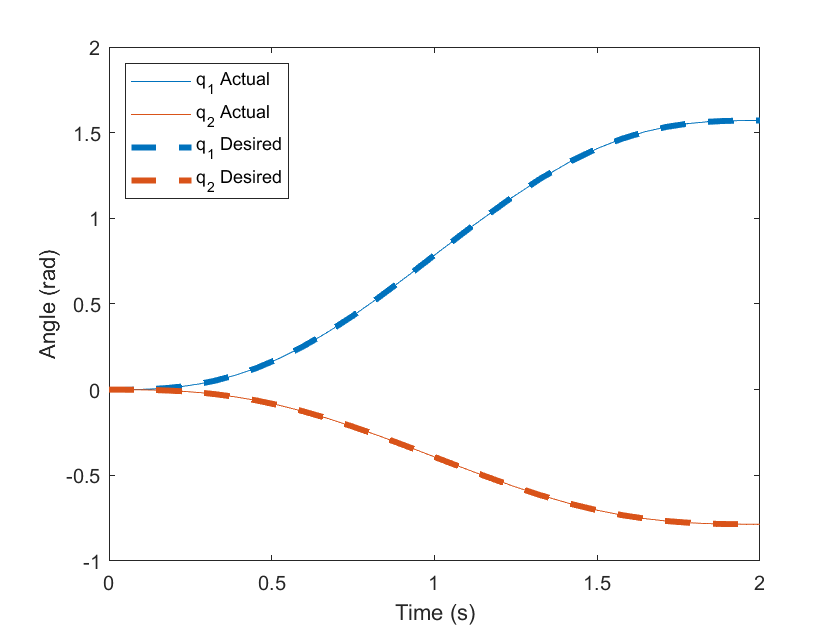

figure
plot(t,y(:,1:2))
hold on
% Reset color order
ax = gca;
ax.ColorOrderIndex = 1;
plot(t,qd,'--','LineWidth',3)
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('show','q_1 Actual','q_2 Actual','q_1 Desired','q_2 Desired')
legend('Location','NorthWest')

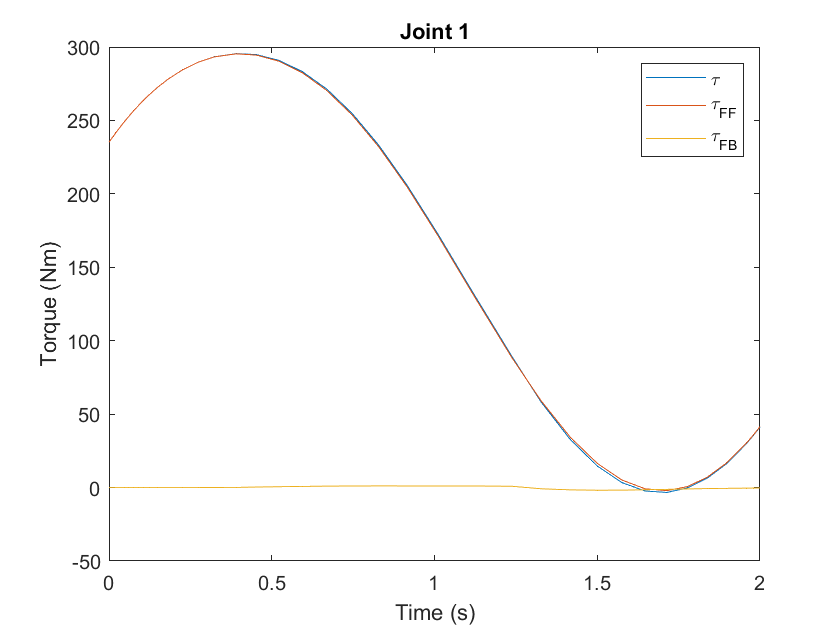


figure
plot(t,tau(1,:), t,tauFF(1,:), t,tauFB(1,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 1')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

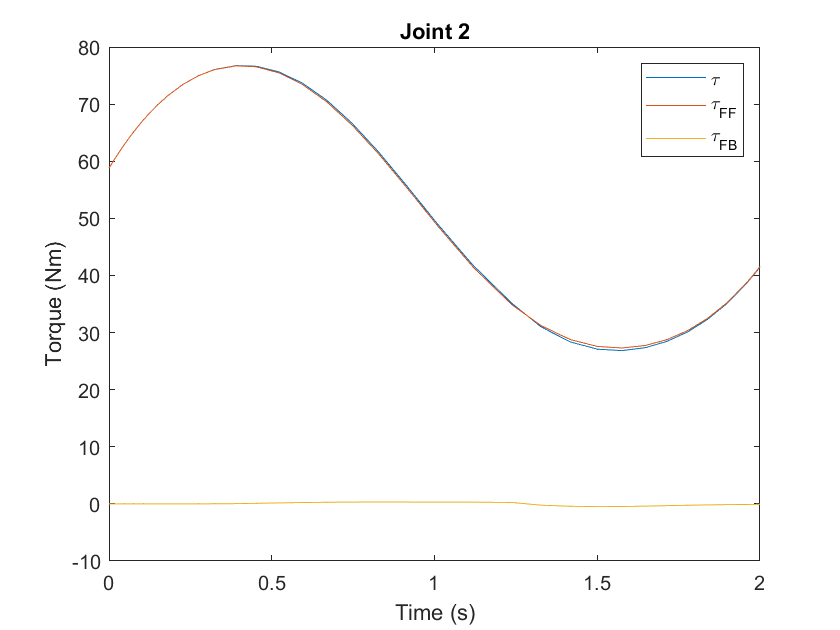


figure
plot(t,tau(2,:), t,tauFF(2,:), t,tauFB(2,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 2')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

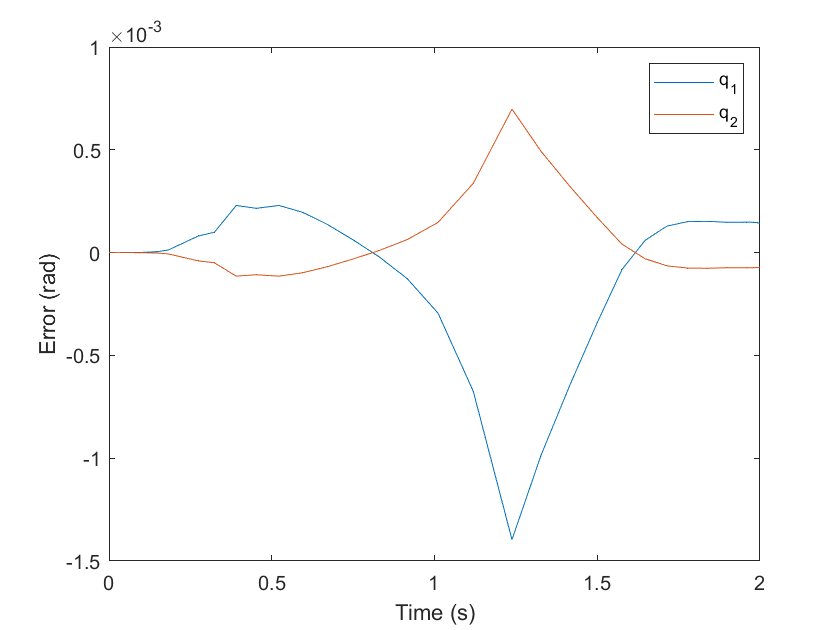


figure
plot(t,e)
xlabel('Time (s)')
ylabel('Error (rad)')
legend('show','q_1','q_2')

### Discuss

## Part b) There is a disturbance

### Simulate

Before simulating, change the initial conditions (y0Pert) to something else.

y0Pert = [1 1 1 1]'

y0Pert =      1
     1
     1
     1


[t, y] = ode23(@twoLinkODE_withTorque,[0 2],y0Pert);

### Calculate torque and error

tau   = zeros(2,length(t));
tauFF = zeros(2,length(t));
tauFB = zeros(2,length(t));
e     = zeros(2,length(t));
qd    = zeros(2,length(t));
for i=1:length(t)
    [tau(:,i), tauFF(:,i), tauFB(:,i), e(:,i), qd(:,i)] = calculateTorque(t(i),y(i,:)');
end

### Plot

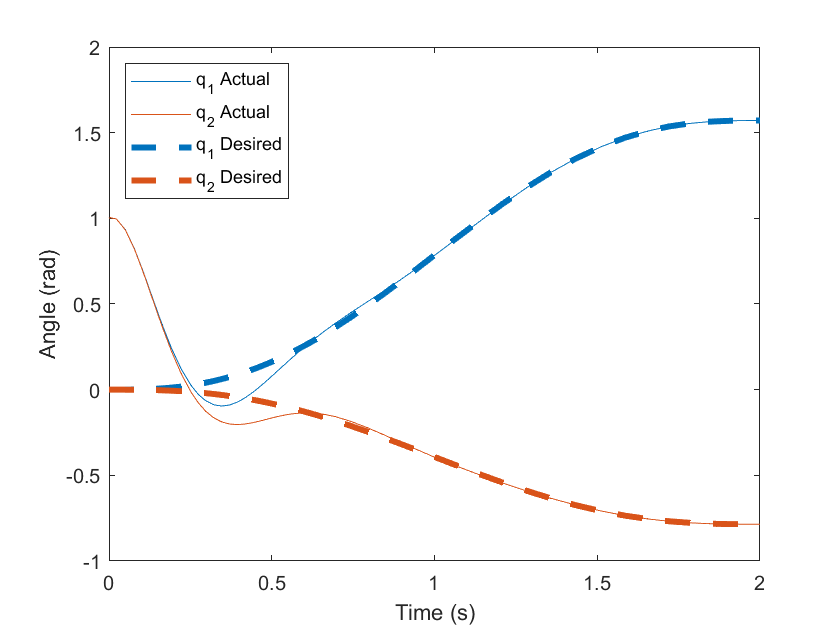

figure
plot(t,y(:,1:2))
hold on
% Reset color order
ax = gca;
ax.ColorOrderIndex = 1;
plot(t,qd,'--','LineWidth',3)
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('show','q_1 Actual','q_2 Actual','q_1 Desired','q_2 Desired')
legend('Location','NorthWest')

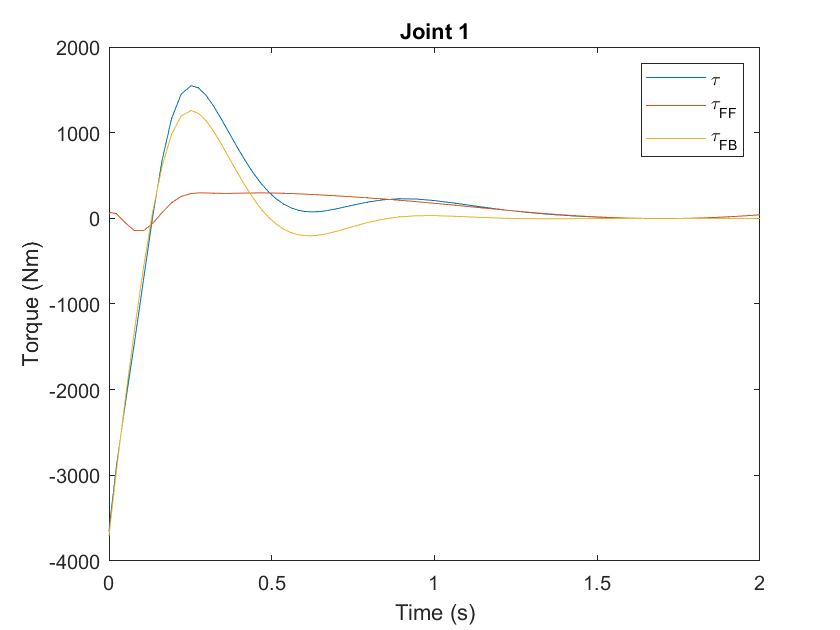


figure
plot(t,tau(1,:), t,tauFF(1,:), t,tauFB(1,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 1')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

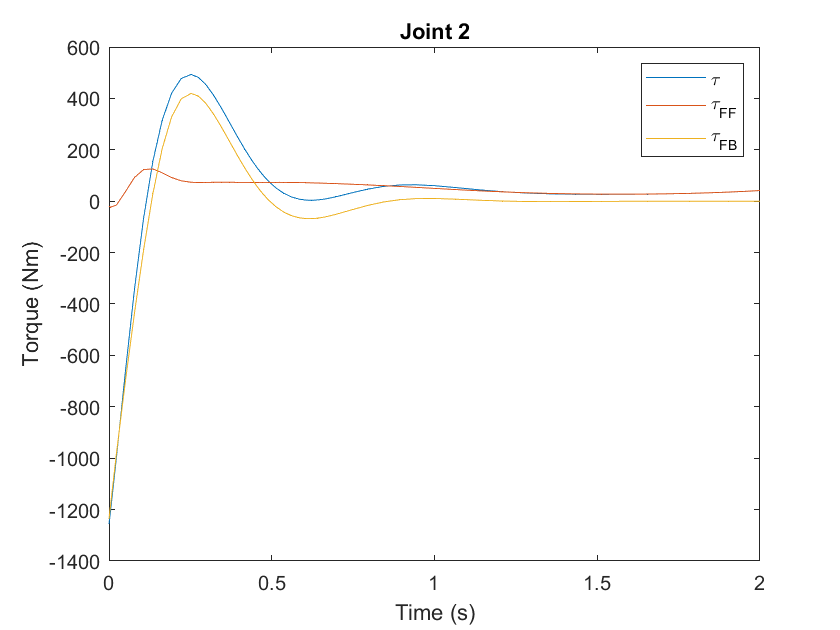


figure
plot(t,tau(2,:), t,tauFF(2,:), t,tauFB(2,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 2')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

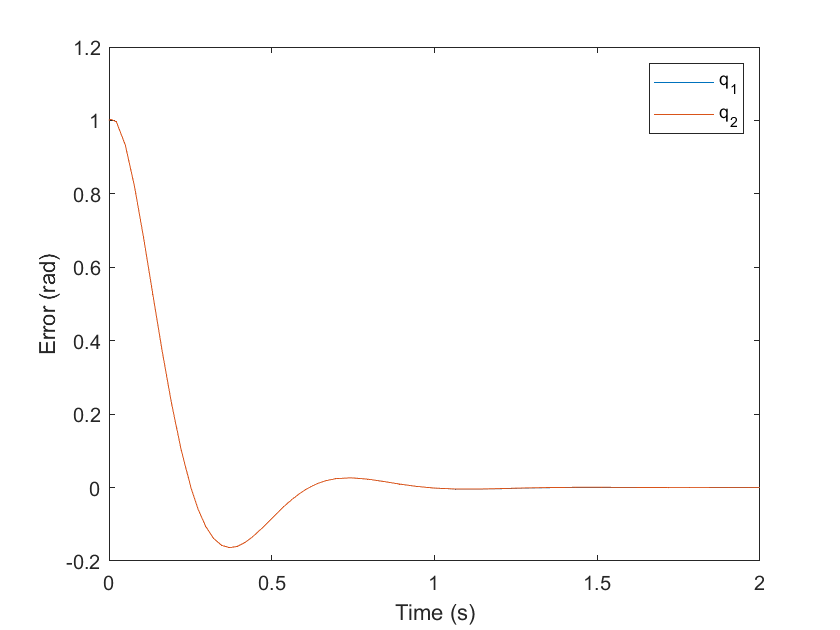


figure
plot(t,e)
xlabel('Time (s)')
ylabel('Error (rad)')
legend('show','q_1','q_2')

### Discuss

## Part c) Only use feedforward control

### Simulate

[t, y] = ode23(@twoLinkODE_withTorqueFF,[0 2],y0Pert);

### Calculate torque and error

tau   = zeros(2,length(t));
tauFF = zeros(2,length(t));
tauFB = zeros(2,length(t));
e     = zeros(2,length(t));
qd    = zeros(2,length(t));
for i=1:length(t)
    [tau(:,i), tauFF(:,i), tauFB(:,i), e(:,i), qd(:,i)] = calculateTorqueFF(t(i),y(i,:)');
end

### Plot

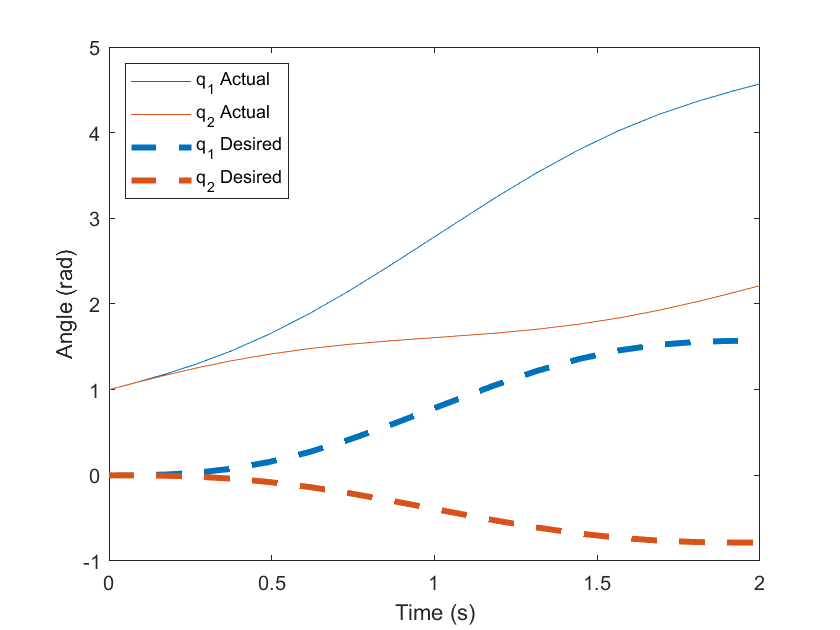

figure
plot(t,y(:,1:2))
hold on
% Reset color order
ax = gca;
ax.ColorOrderIndex = 1;
plot(t,qd,'--','LineWidth',3)
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('show','q_1 Actual','q_2 Actual','q_1 Desired','q_2 Desired')
legend('Location','NorthWest')

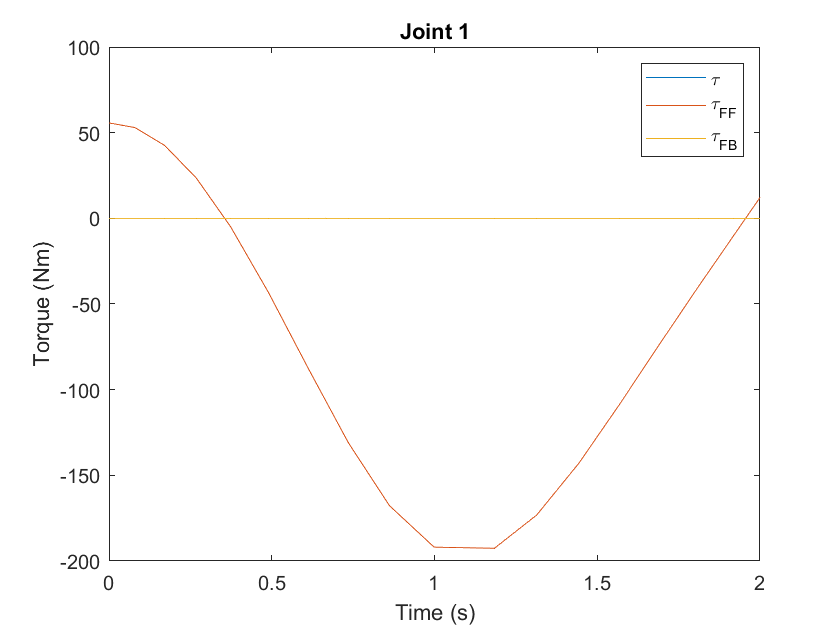


figure
plot(t,tau(1,:), t,tauFF(1,:), t,tauFB(1,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 1')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

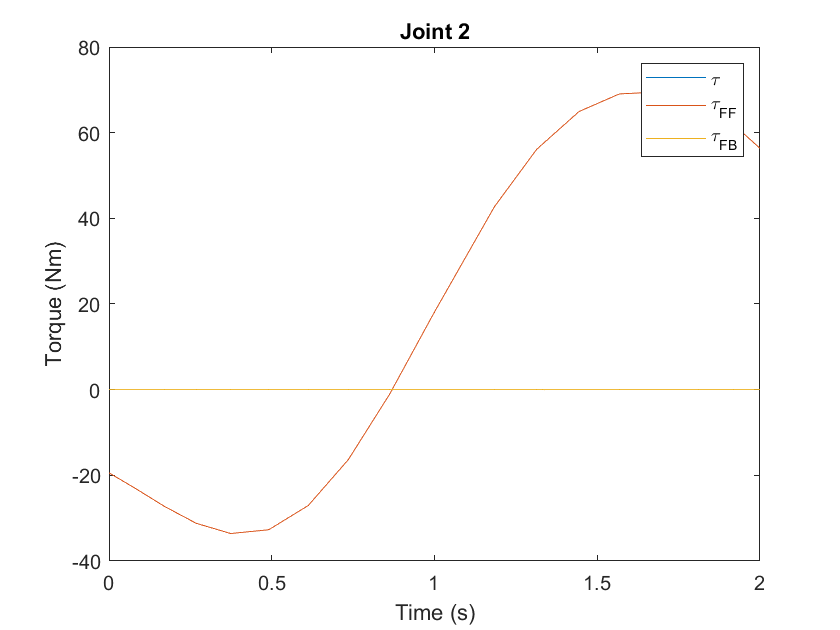


figure
plot(t,tau(2,:), t,tauFF(2,:), t,tauFB(2,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 2')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

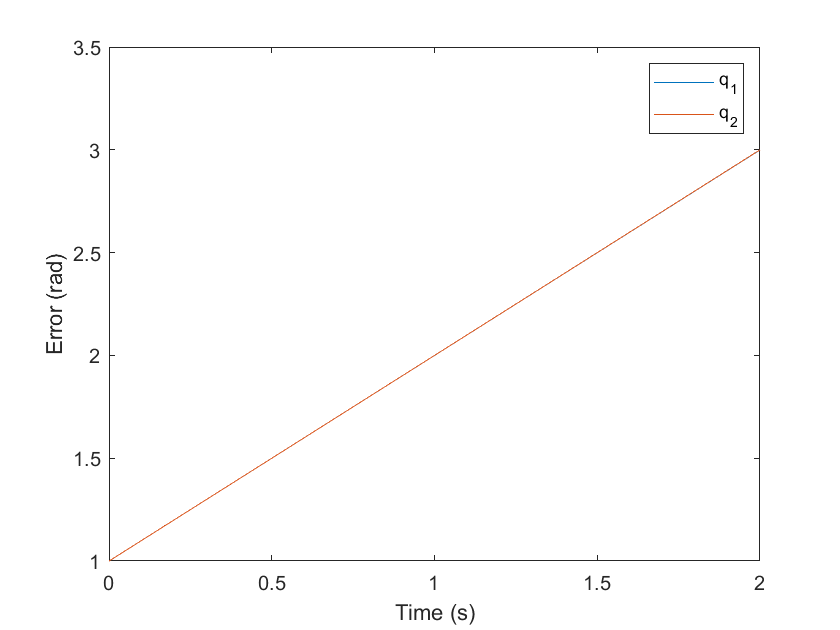


figure
plot(t,e)
xlabel('Time (s)')
ylabel('Error (rad)')
legend('show','q_1','q_2')

### Discuss

## Part d) Only use feedback control

### Simulate

[t, y] = ode23(@twoLinkODE_withTorqueFB,[0 2],y0Pert);

### Calculate torque and error

tau   = zeros(2,length(t));
tauFF = zeros(2,length(t));
tauFB = zeros(2,length(t));
e     = zeros(2,length(t));
qd    = zeros(2,length(t));
for i=1:length(t)
    [tau(:,i), tauFF(:,i), tauFB(:,i), e(:,i), qd(:,i)] = calculateTorqueFB(t(i),y(i,:)');
end

### Plot

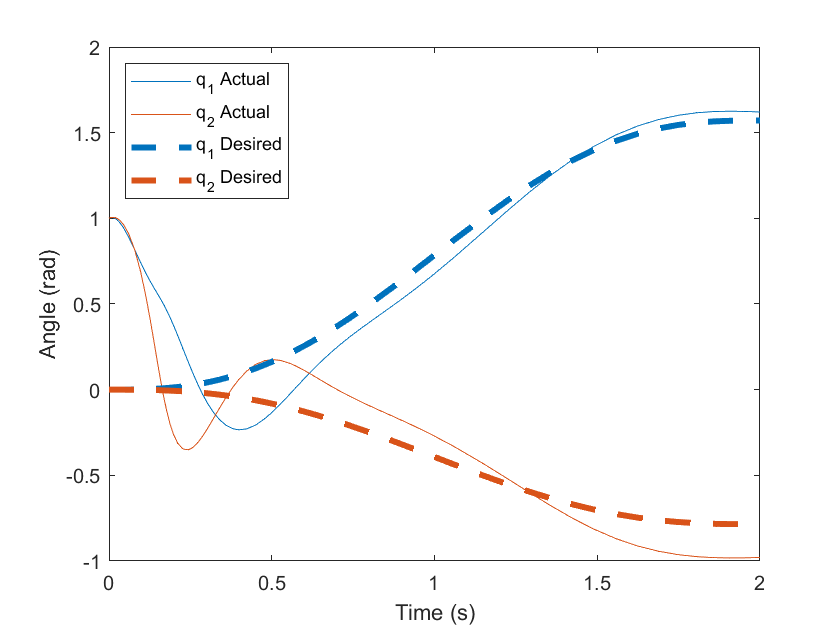

figure
plot(t,y(:,1:2))
hold on
% Reset color order
ax = gca;
ax.ColorOrderIndex = 1;
plot(t,qd,'--','LineWidth',3)
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('show','q_1 Actual','q_2 Actual','q_1 Desired','q_2 Desired')
legend('Location','NorthWest')

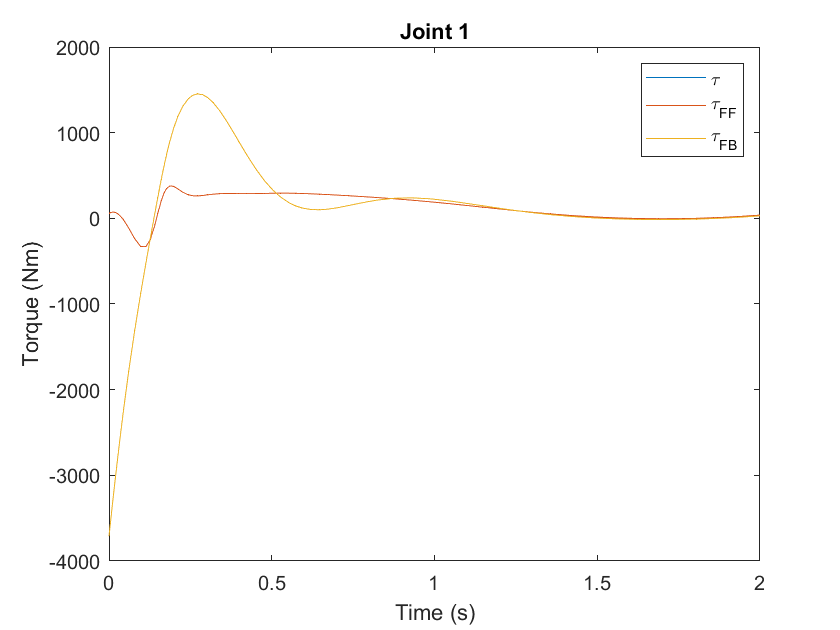


figure
plot(t,tau(1,:), t,tauFF(1,:), t,tauFB(1,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 1')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

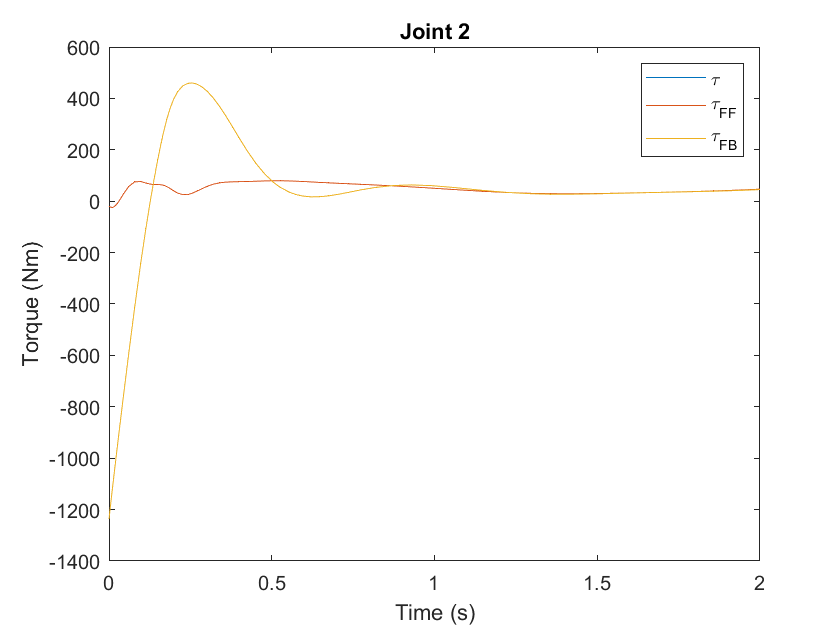


figure
plot(t,tau(2,:), t,tauFF(2,:), t,tauFB(2,:))
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Joint 2')
legend('show','\tau','\tau_{FF}','\tau_{FB}')

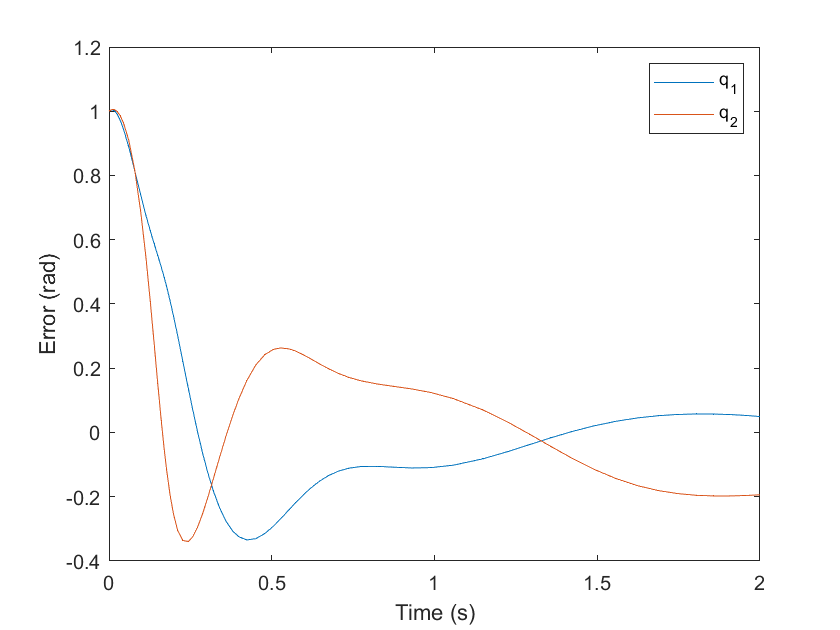


figure
plot(t,e)
xlabel('Time (s)')
ylabel('Error (rad)')
legend('show','q_1','q_2')

### Discuss